clear
tspan = [0 100];

%定常値を設定
%{
judge ok!

安定　条件clear
steady_delta = [1.1;1.6;1.4];
steady_deltaomega = [0;0;0];
steady_E = [1;2.5;2.1];
% W が単調減少する特異的な error ?
error = [1;1;1;0;0;0;1;1;1];

安定じゃない
steady_delta = [-0.2607;0.6415;0.4656];
steady_deltaomega = [0;0;0];
steady_E = [4.3303;3.2225;2.2370];

ぎり安定
steady_delta = [-1.25664;0;0];
steady_deltaomega = [0;0;0];
steady_E = [3.2225;3.2225;3.2225];

不安定
steady_delta = [0.942478;0;-1.41372];
steady_deltaomega = [0;0;0];
steady_E = [3.2225;3.2225;3.2225];

めちゃ安定?
steady_delta = [0.15708;0;-0.15708];
steady_deltaomega = [0;0;0];
steady_E = [3.2225;3.2225;3.2225];

% W が単調減少する ->
error = [0;0;0;0;0;0;0.1;-0.1;-0.1];
% slackで送ったもの -> 
error = [0.01;0;0;0;0;0;0.1;-0.1;-0.1];
% 条件clear　W良さげ -> 
error = [0;0;0.0001;0;0;0;0.1;-0.1;-0.1];
% 条件clearだけどすんごい揺れる -> 
error = [0;0;0.01;0;0;0;0;0;0];


% W_Gred W_G 良さげ　条件clear
steady_delta = [1.1;1.6;1.4];
steady_deltaomega = [0;0;0];
steady_E = [1;2.5;2.1];
error = [0.01;0;0;0;0;0;0.1;-0.1;-0.1];

steady_delta = [0.15708;0;-0.15708];
steady_deltaomega = [0;0;0];
steady_E = [3.2225;3.2225;3.2225];
error = [0;0;0.0001;0;0;0;0.1;-0.1;-0.1];

steady_delta = [0.15708;0;-0.15708];
steady_deltaomega = [0;0;0];
steady_E = [3.2225;3.2225;3.2225];
error = [0.01;0;0;0;0;0;0.1;-0.1;-0.1];


%条件clear びみょ
steady_delta = [0.15708;0;-0.15708];
steady_deltaomega = [0;0;0];
steady_E = [3.2225;3.2225;3.2225];
error = [0;0.1;0;0;0;0;0;-0.5;0];


% 条件clear W_Gred はokなのに W_G だめ
steady_delta = [1.1;1.6;1.4];
steady_deltaomega = [0;0;0];
steady_E = [1;2.5;2.1];
error = [0;0;0.1;0;0;0;0;0;0];

steady_delta = [1.1;1.6;1.4];
steady_deltaomega = [0;0;0];
steady_E = [1;2.5;2.1];
error = [0;0;0.1;0;0;0;0.5;0;0];

steady_delta = [1.1;1.6;1.4];
steady_deltaomega = [0;0;0];
steady_E = [1;2.5;2.1];
error = [0;0;0.1;0;0;0;0;0;0];

steady_delta = [0.15708;0;-0.15708];
steady_deltaomega = [0;0;0];
steady_E = [3.2225;3.2225;3.2225];
error = [0;0.1;0;0;0;0;0;0;0];
errorのEに値を入れるか入れないかで安定性が変わる？

Eに入れてもだめ。
steady_delta = [0.15708;0;-0.15708];
steady_deltaomega = [0;0;0];
steady_E = [3.2225;3.2225;3.2225];
error = [0;0.1;0;0;0;0;0.5;0;0];

%===================================
%同じ平衡点で、初期値を変えたとき

% Good
*
steady_delta = [0.15708;0;-0.15708];
steady_deltaomega = [0;0;0];
steady_E = [3.2225;3.2225;3.2225];
c
% Not Bad
steady_delta = [0.15708;0;-0.15708];
steady_deltaomega = [0;0;0];
steady_E = [3.2225;3.2225;3.2225];
error = [0;0.1;0;0;0;0;0;-0.5;0];

*
steady_delta = [0.15708;0;-0.15708];
steady_deltaomega = [0;0;0];
steady_E = [3.2225;3.2225;3.2225];
error = [0;0.1;0;0;0;0;0.1;-0.1;-0.1];

% Bad
*
steady_delta = [0.15708;0;-0.15708];
steady_deltaomega = [0;0;0];
steady_E = [3.2225;3.2225;3.2225];
error = [0;0.1;0;0;0;0;0;0;0];

% Too Bad
*
steady_delta = [0.15708;0;-0.15708];
steady_deltaomega = [0;0;0];
steady_E = [3.2225;3.2225;3.2225];
error = [0;0.1;0;0;0;0;0.5;0;0];
%====================================

% Best Exmaple
steady_delta = [0.15708;0;-0.15708];
steady_deltaomega = [0;0;0];
steady_E = [3.2225;3.2225;3.2225];
error = [0;0.1;0;0.01;0;0;0.1;-0.1;-0.1];

% 重なってて逆位相が見やすい
error = [0;0.1;0;0;0.01;0;0.5;0;0];

%}

% Ured_G, W_F, Wred_G, W_F + Wred_G のグラフを表示するなら 1 . 表示しないなら 0.
flag_accum = 1;

% diff( W_F + Wred_G ) のグラフを表示するなら 1 . 表示しないなら 0.
flag_accum_diff = 1;

steady_delta = [0.15708;0;-0.15708];
steady_deltaomega = [0;0;0];
steady_E = [3.2225;3.2225;3.2225];
error = [0;0.1;0;0;0.01;0;0.5;0;0];




steady_generator_state = [steady_delta; steady_deltaomega; steady_E];

initial_generator_state = steady_generator_state + error;

judge_steady(initial_generator_state)

線形システムの漸近安定性
Matrix: psi is steady.
Kernel of Matrix:B is span{1}.
Kernel of Matrix:L is span{1}.
受動送電条件(ⅰ),(ⅲ)
Matrix: A is steady.
Matrix: Lo=L-C*inv(A)*B　is symmetric positive definite.


judge_steady(steady_generator_state)

線形システムの漸近安定性
Matrix: psi is steady.
Kernel of Matrix:B is span{1}.
Kernel of Matrix:L is span{1}.
受動送電条件(ⅰ),(ⅲ)
Matrix: A is steady.
Matrix: Lo=L-C*inv(A)*B　is symmetric positive semi-definite


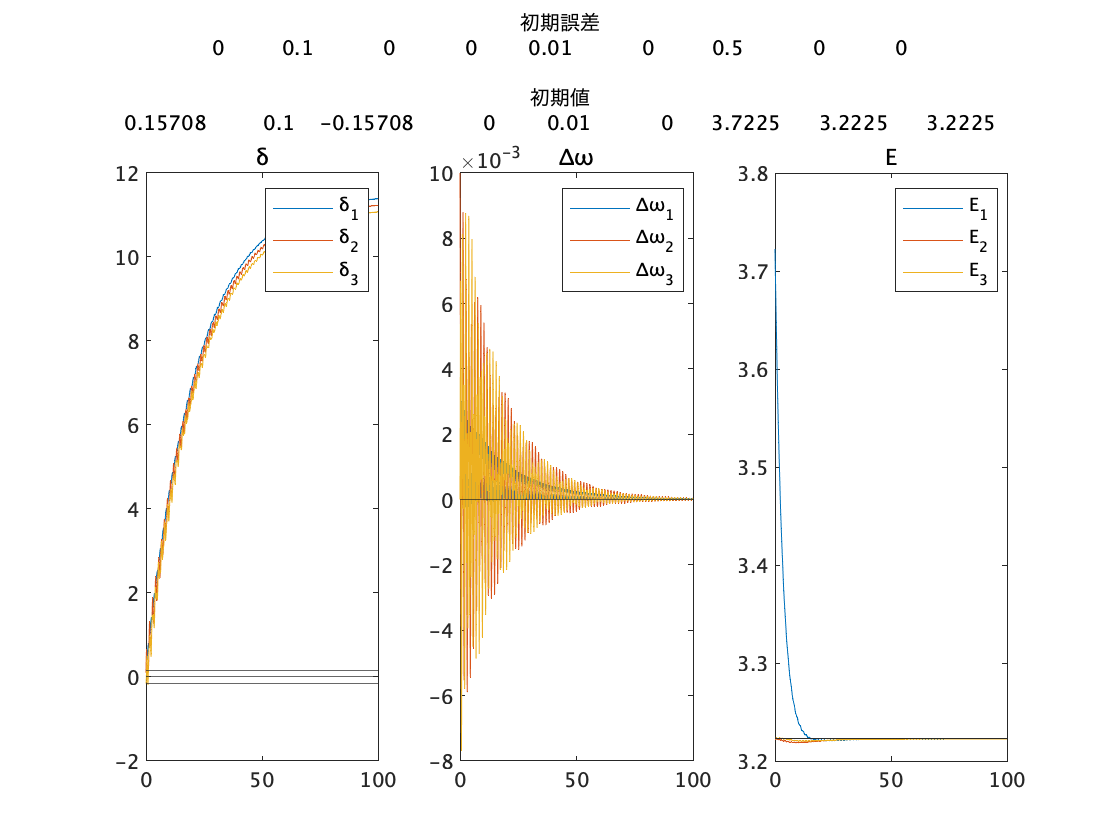

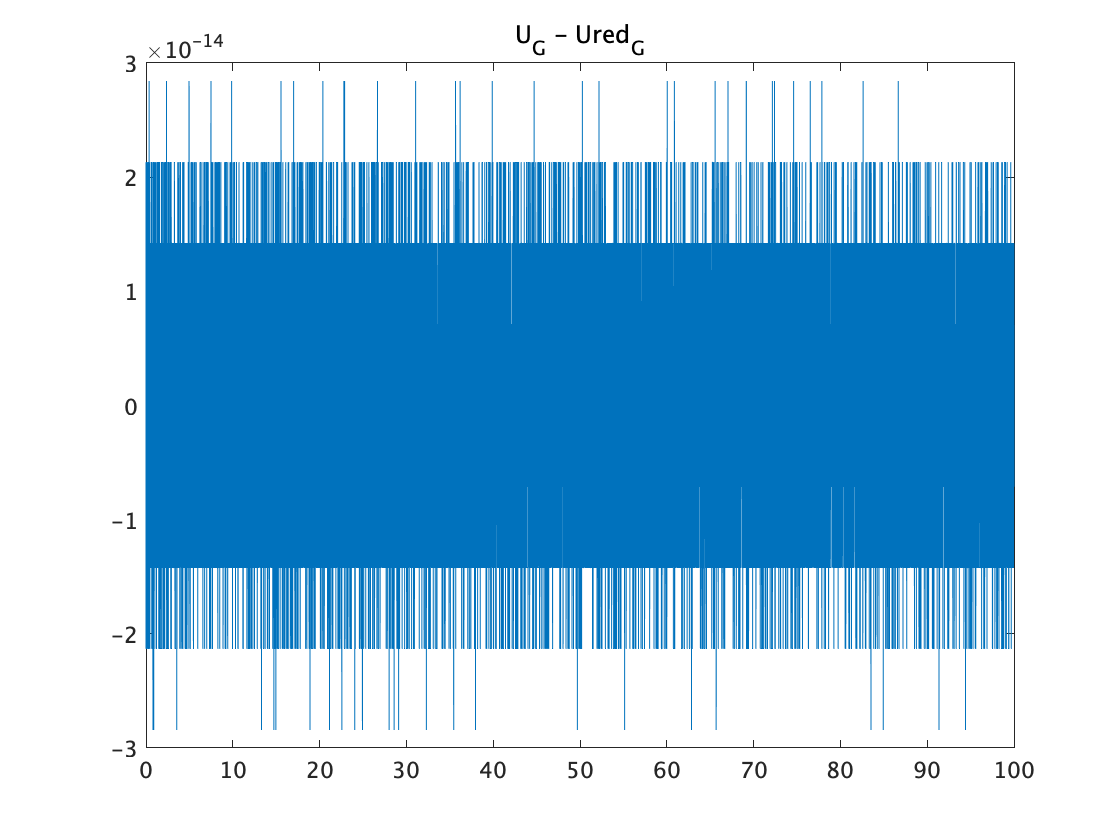

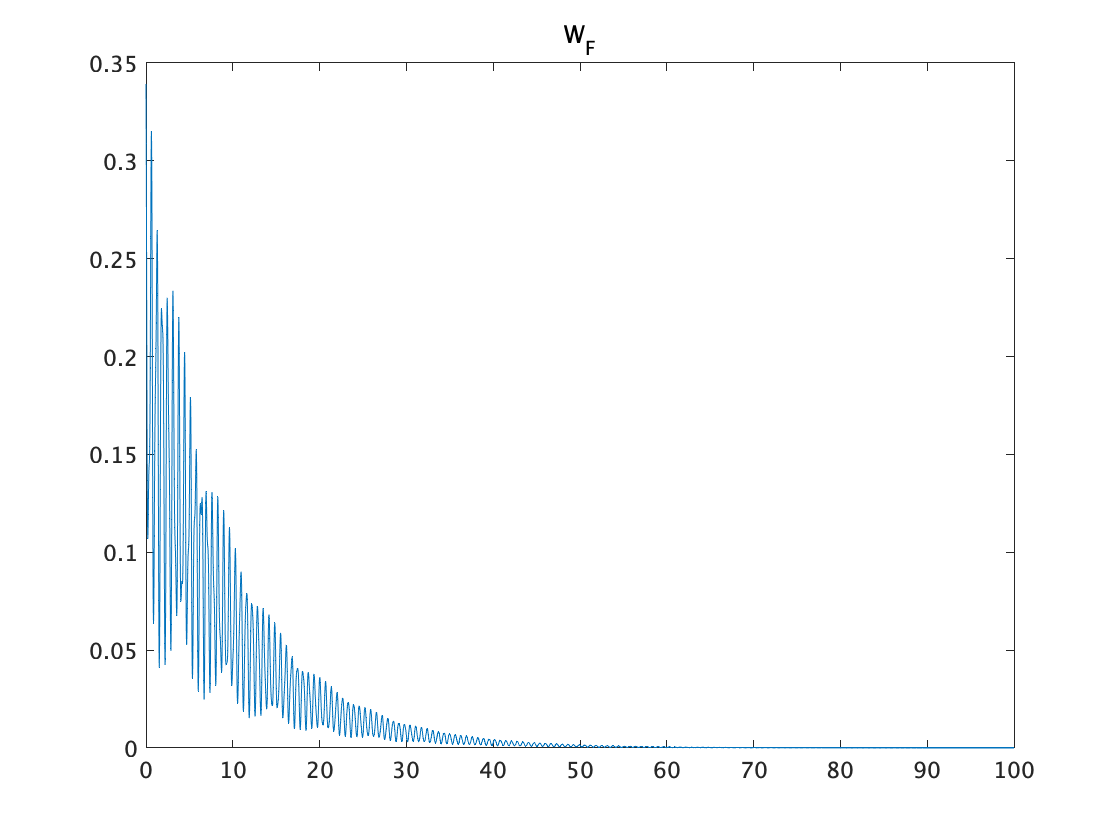

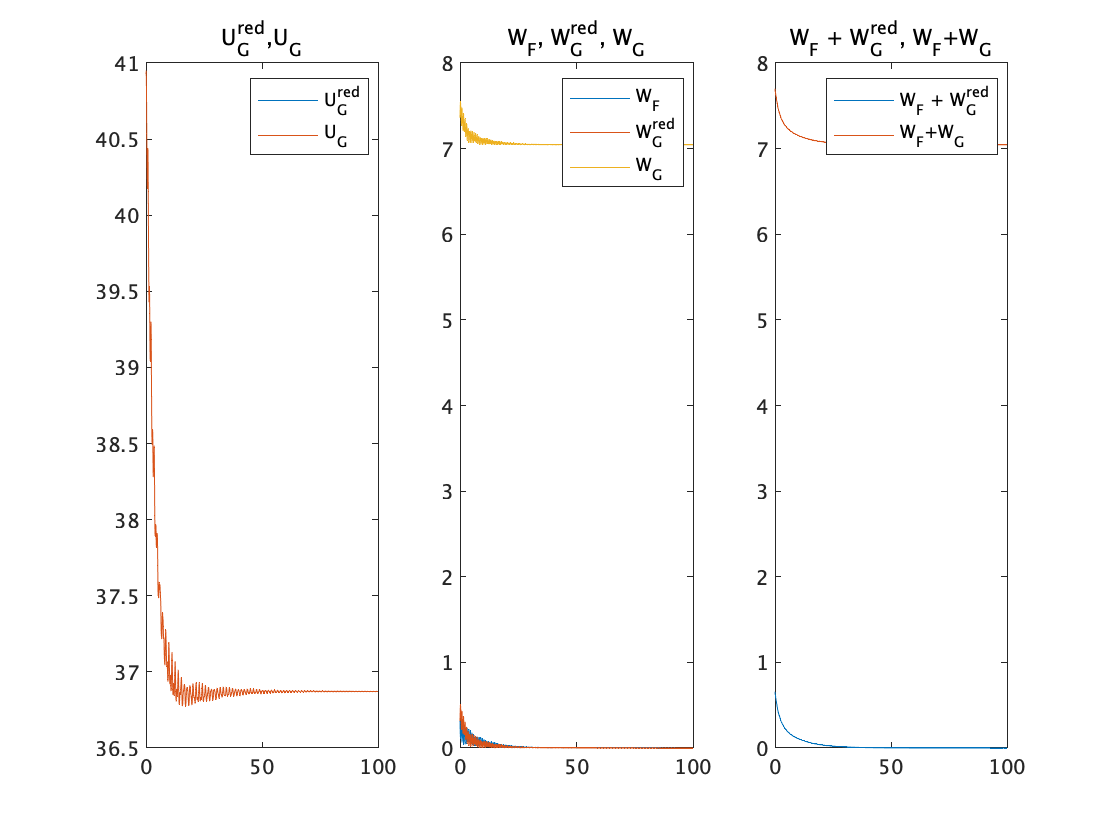

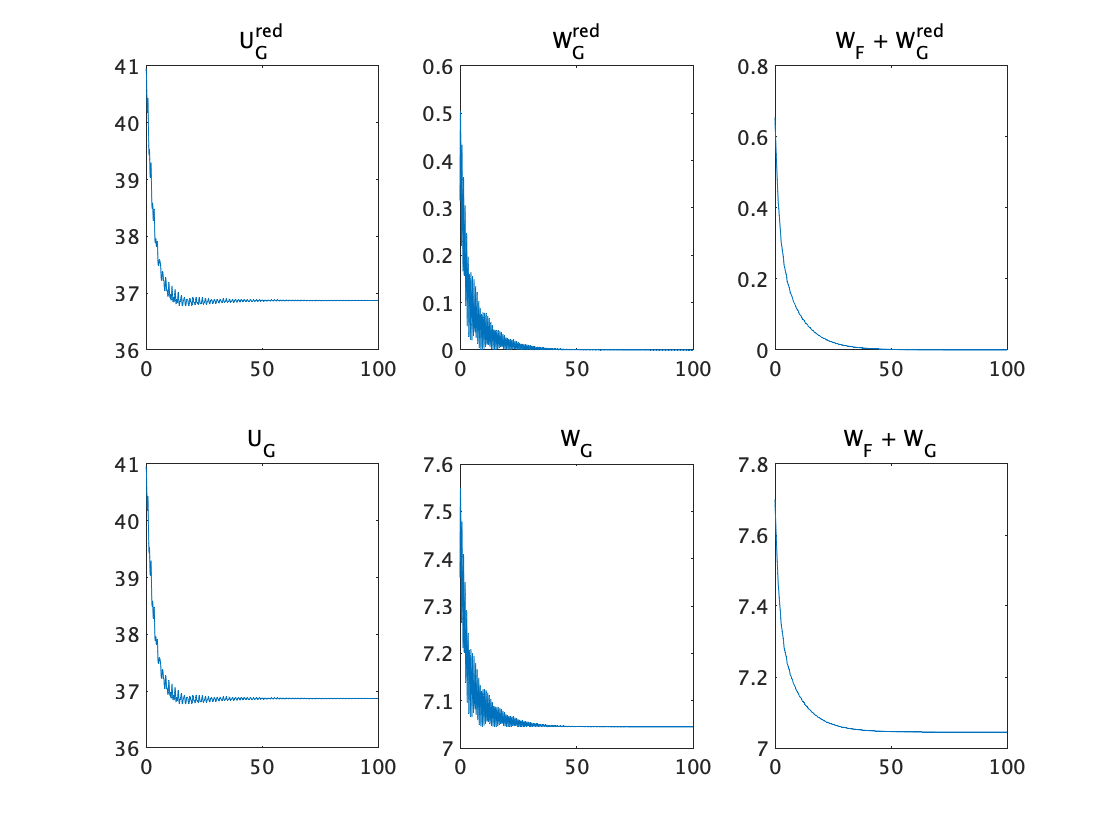

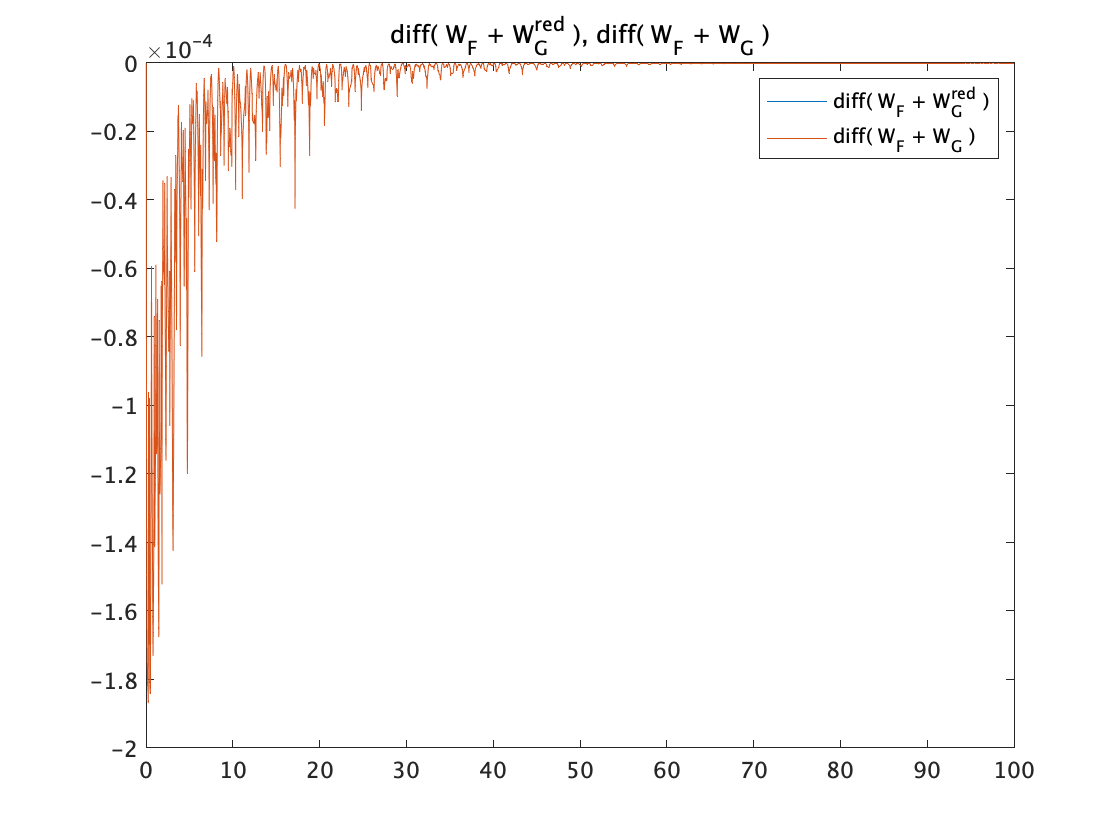

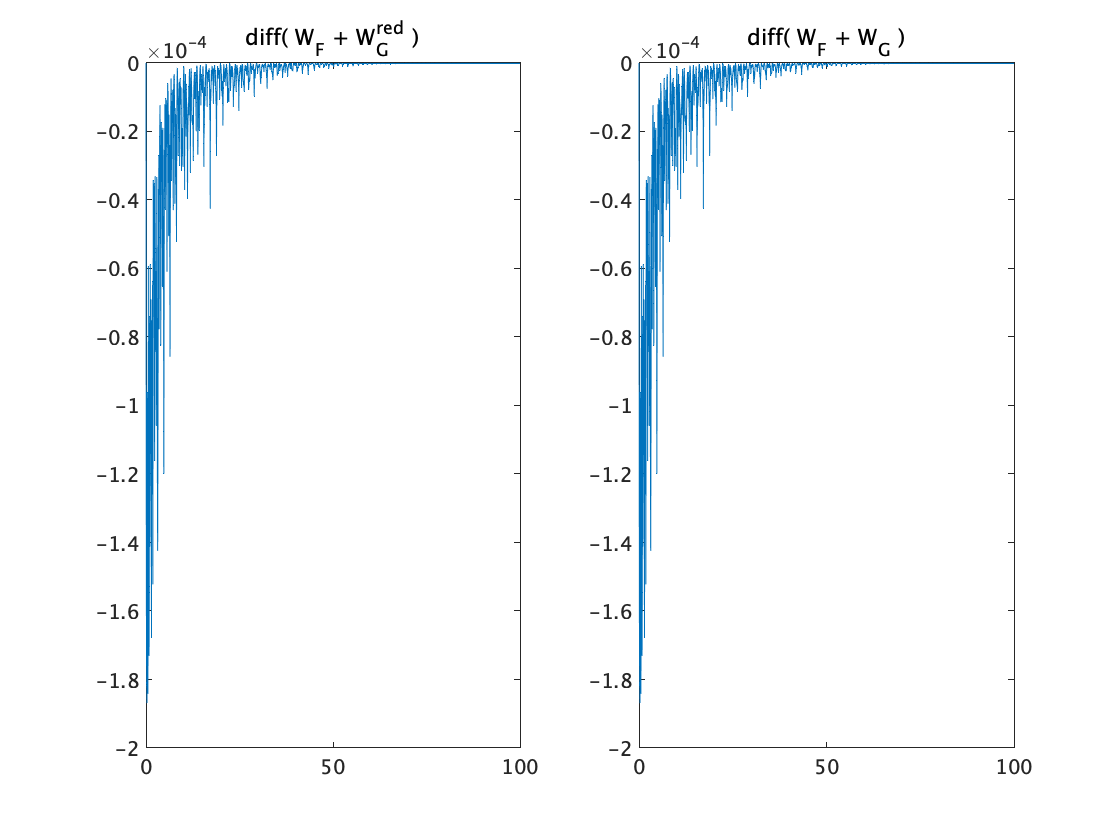

max_diff_W_FGred = -3.9568e-12

max_diff_W_FG = -3.9497e-12


plot_generator_state_wrap = @(error,initial_generator_state) plot_generator_state(error,tspan,initial_generator_state,steady_generator_state,flag_accum,flag_accum_diff);

figure;
plot_generator_state_wrap(error,initial_generator_state);